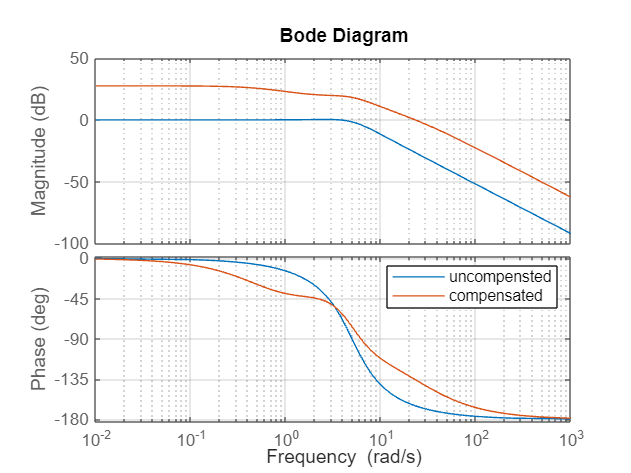

% Case 1: G1(s) = 9/(s^2 + 4 s + 9)
s = tf('s');
G1 = 25/(s^2 + 6*s + 25);%%open loopTf for uncompensated sytem

% Proposed compensators
C_lead = 30*(s+2)/(s+24);%%lead comaparator
C_lag  = (s+4)/(s+0.4);
C_T= C_lead * C_lag;%%lead and lag in cascade

% Closed-loop (unity feedback)
T1 = feedback(C_T * G1, 1);


% bode plot for uncompenated system and compensated system
figure;
bode(G1, C_T*G1); 
legend('uncompensted','compensated');
grid on;

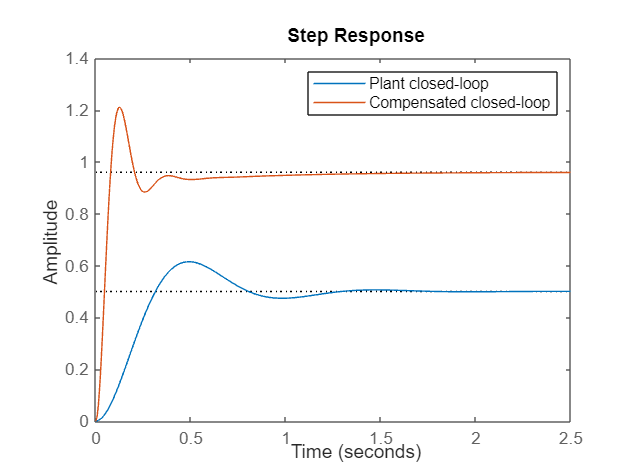

%%step polots for uncompensatedand fully_compensted system
figure; 
step(G1/(1+G1), T1); 
legend('Plant closed-loop','Compensated closed-loop');

S1 = stepinfo(T1);
disp('Step info for compensated case 1:'); 

Step info for compensated case 1:


disp(S1);

         RiseTime: 0.0532
    TransientTime: 0.7180
     SettlingTime: 0.7180
      SettlingMin: 0.8835
      SettlingMax: 1.2114
        Overshoot: 26.1912
       Undershoot: 0
             Peak: 1.2114
         PeakTime: 0.1254



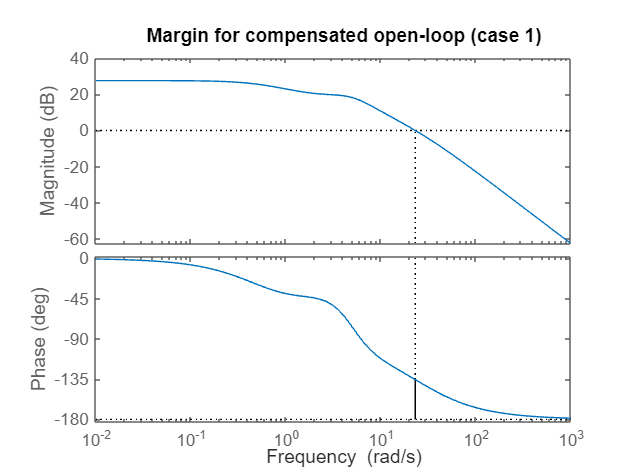

%%margin plot for the compensated system 
figure; 
margin(C_T*G1); 
title('Margin for compensated open-loop (case 1)');